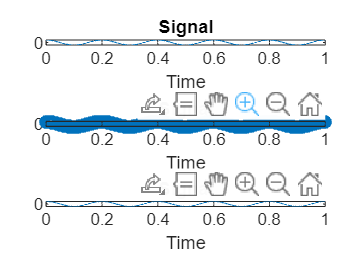

Fs=1000;  %sampling frequency
T=1/Fs;
t_cont=0:0.001:1;

%signal
m = 2 * cos(2*pi*5*t_cont);

%sampled signal
t_sample = 0:T:1;
sample = 2*cos(2*pi*5*t_sample);

%reconstruction
recons_zoh=zeros(1,length(t_cont));
for i = 1:length(t_sample)
    index = find(t_cont>=t_sample(i),1,"first");
    recons_zoh(index)=sample(i);
end

recons_linear = interp1(t_sample,sample,t_cont,"linear");

figure;
subplot(3,1,1);
plot(t_cont, m); %signal plot
title('Signal');
xlabel('Time');
ylabel('Amplitude');

subplot(3,1,2);
stem(t_sample,sample); %sample signal plot
title('Signal');
xlabel('Time');
ylabel('Amplitude');

subplot(3,1,3);
plot(t_cont,recons_linear); %reconstr signal plot
title('Signal');
xlabel('Time');
ylabel('Amplitude');